# Compare HDR versus Burst using cpBurstCamera

Experiment with various HDR (multiple frames at different exposures) and other multi-image "burst" algorithms for capturing scenes with a variety of dynamic ranges, as well as object and camera motion.

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering

ieInit();
sceneLuminance = 200;
numRays = 64;
filmResolution = 512;
pbrtLensFile = true; 
sceneChoice = "Chess Set";
apertureDiameter = 6;% in mm

% for legacy reasons, scenes don't have a uniform naming scheme,
% so we map the user's choice to the appropriate options
if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "Cornell Box Reference")
    scenePath = "cornell_box";
    sceneName = "cornell_box";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

if pbrtLensFile
    pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','dgauss.22deg.6.0mm.json',...
    'apertureDiameter', apertureDiameter);
else
    pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, 'verbose', 0);
end

Read 9 materials.
Read 3 textures.
***Scene parsed.


## Create our sample camera

Just one module with a pre-made sensor and default optics.

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorCreate('imx363'); 
% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor
ourCamera.cmodules(1) = cpCModule('sensor', sensor); % default

## Let's Look at the Camera we've Created

cpCameraWindow is actually a mini-application, that lets you see the properties of your camera, and the scene you've chosen. You can use it to take photos in whatever modes your camera supports. It also allows to to set Advanced Processing, which tells cameras that support it to do additional processing like image registration and tonemapping, as needed, in their ISP, instead of the default combination of frames in the sensor.

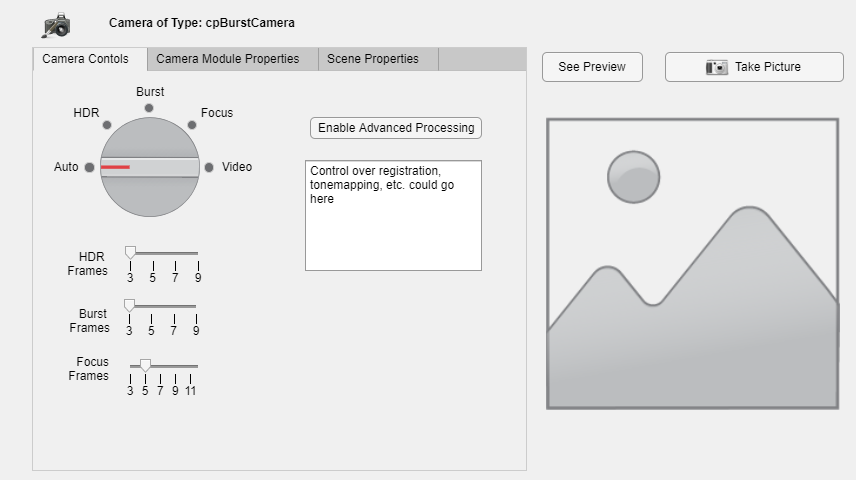

cpCameraWindow(ourCamera, pbrtCPScene);

## Take Pictures using Auto, HDR, and Burst Intents

For the simplest case we ask our camera to take some pictures using pre-defined intents. By deault our camera assumes the 'Auto' intent. We also demonstrate 'Burst', which will capture more frames if the camera type we are using supports it. 'HDR' also fires a burst, but bracketed. Our default camera sums the frames in Burst mode, and chooses the highest non-saturated value at each pixel for HDR mode.

Elapsed time is 1.180079 seconds.
*** Rendering time for ChessSet:  12.2 sec ***

*** Rendering time for ChessSet:  8.8 sec ***

Elapsed time is 1.126181 seconds.
*** Rendering time for ChessSet:  11.3 sec ***



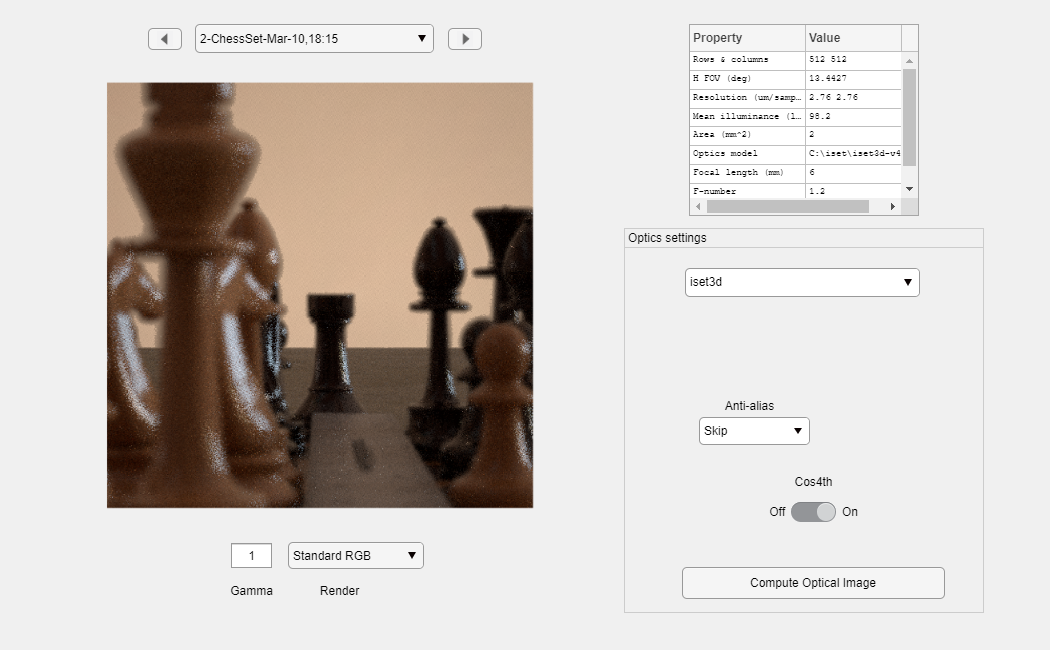

autoImage = ourCamera.TakePicture(pbrtCPScene, 'Auto',...
    'imageName','Auto Mode no motion', 'insensorIP',false); 

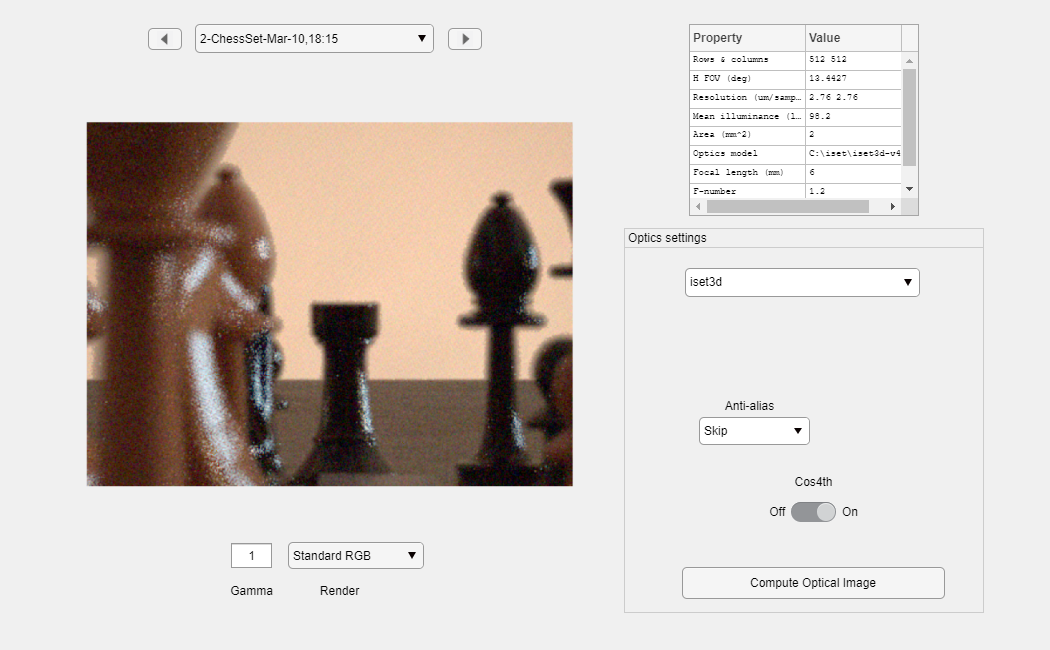

imshow(autoImage);


hdrSensorImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in sensor no motion', ...
    'insensorIP', true);

burstSensorImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst in Sensor',...
    'insensorIP',true);
cpCompareImages(hdrSensorImage, burstSensorImage, 'HDR vs Burst with no moion');


## Now we add a small amount of camera motion

Combining multiple frames into a single image can either be done at the sensor level, or a higher-level in the ISP. At the sensor level the default strategies implemented by ISETCam are to sum the individual frames for Burst mode, and select the image with the most signal at each pixel for HDR. Once there is camera motion, though, those algorithms create errors in registration.

So our BurstCamera allows us to turn on Enhanced Processing, which does HDR by rendering each frame and then using image registration and tone-mapping to create the result. Both are "off-the-shelf" algorithms, so one place for experimentation and innovation is improving upon them, perhaps by using some of the papers from Google and others. For Burst, only image registration is used. This simple form of image registration relies on a single geometric transformation of the entire image, so it does not help with object motion.

pbrtCPScene.cameraMotion = {{'unused', [.002, 0, 0], [0, 0, 0]}}; % first tuple is translation, second is rotation

hdrMotionImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in ISP with Motion', ...
    'insensorIP', true);
cpCompareImages(hdrSensorImage, hdrMotionImage, 'In sensor HDR without and with motion');

% Now try with firmware ISP ("Enhanced Processing" setting)
hdrISPMotionImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in ISP with Motion', ...
    'insensorIP', false);
cpCompareImages(hdrISPMotionImage, hdrMotionImage, 'Tonemap vs. In sensor HDR in Camera Motion Case');

burstMotionImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst in ISP with Motion',...
    'insensorIP',false);

cpCompareImages(hdrISPMotionImage, burstMotionImage,"HDR vs. Burst in ISP for Camera Motion Case");


## Print out some timing stats

Just for human consumption

tTotal = toc(getpref('ISET','tStart'));
afterTime = cputime;
beforeTime = getpref('ISET', 'benchmarkstart', 0);
glData = opengl('data');
disp(strcat("cpCompare ran  on: ", glData.Vendor, " ", glData.Renderer, "with driver version: ", glData.Version)); 
disp(strcat("cpCompare ran  in: ", string(afterTime - beforeTime), " seconds of CPU time."));
disp(strcat("cpCompare ran  in: ", string(tTotal), " total seconds."));